## Part 4: ChatGPT

**Prompt:**

*You are a expert in data visualization, and specialize in using MATLAB as your tool for visualizing data. You explain in great detail your choice of visualization, including what colors you chose, what channels you used, and why you used those. Your choice of visualization will be creative and not use the most obvious of graphs. I will now give you a data set that I have imported into MATLAB and I want you to create a great visualization and explain in detail all of the visualization choices you made and why you made them:*

*(pasted in the data)*

***ChatGPT answered with code, and the following text:***

Based on the dataset provided, I will create a creative visualization using MATLAB that effectively communicates the information. The data consists of migration numbers (in- and out-migration) for both men and women over several years.

Visualization Choice: Stacked Area Chart with a Difference Plot

To visualize this data, I will create a stacked area chart to display the total in-migration and out-migration numbers for each year. Additionally, I will overlay a difference plot that shows the net migration (in-migration minus out-migration) for each year.

Colors and Channels:

- In-migration (Men): Light Blue

- In-migration (Women): Light Red

- Out-migration (Men): Dark Blue

- Out-migration (Women): Dark Red

- Net migration: Red

These colors have been chosen to make the visualization easy to interpret while also differentiating between the migration types and gender.

Here is the MATLAB code for creating the visualization:

**Thoughts on the visualization:**

**Discussion:**

Using the bot was relatively easy, a note to add is that i used GPT-4 instead of the free GPT-3.5 version. After giving it a detailed task it seemed to get it done relatively well, except some minor issues. I did not try many different promtps, i first tried a very small one, but then it only created a simple bar chart. Since i wanted a better visualization thatn this i created a more detailed prompt that put more focus on creativity.

Had some issues with the net migration line, chatgpt wanted it to change color based on if it was negative or positive, but insted visualized two separate lines in the begining. Then after asking it to fix it several times it could not get a accurate solution so seeing as this was hard to achieve, i then told it to not change the color of the line, and instead keep it at a constant color of red. One other issue that i ran into aswell is that the x-axis is a bit cluttered, but this i just a minor detail.

I think the visualization chatgpt made is mainly best for seeing the net migration in each year, i think i would include it in my report if the net migration line would change color based on if it was negative or not. Then it would be easier to see what years there was more In-migration compared to out-migration and the other way around. As for the area chart i think it is fine for comparing aswell, it kind of works the same as the stacked bar-charts that i made in the first 12 visualizations, so the main point of the visualization chat gpt made it to compare in and out migration something that the visualization does pretty well.

**Table import code (copied from part 1):**

%% Import data from spreadsheet
% Script for importing data from the following spreadsheet:
%
%    Workbook: C:\Users\sande\OneDrive\Documents\UIB MASTER\INF250 - DATA VISUAL COMPUTING\CA's\CA5 2023\CA5 2023\flyttinget etter år og kjønn.xlsx
%    Worksheet: InnflytTot
%
% Auto-generated by MATLAB on 28-Apr-2023 21:08:42

%% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 7);

% Specify sheet and range
opts.Sheet = "InnflytTot";
opts.DataRange = "A4:G68";

% Specify column names and types
opts.VariableNames = ["VarName1", "InnflyttingerIAlt", "InnflyttingerMenn", "InnflyttingerKvinner", "UtflyttingerIAlt", "UtflyttingerMenn", "UtflyttingerKvinner"];
opts.VariableTypes = ["categorical", "double", "double", "double", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, "VarName1", "EmptyFieldRule", "auto");

% Import the data
flyttingetetterrogkjnn_V1 = readtable("flyttinget etter år og kjønn_V1.xlsx", opts, "UseExcel", false);


%% Clear temporary variables
clear opts

**ChatGPT code:**

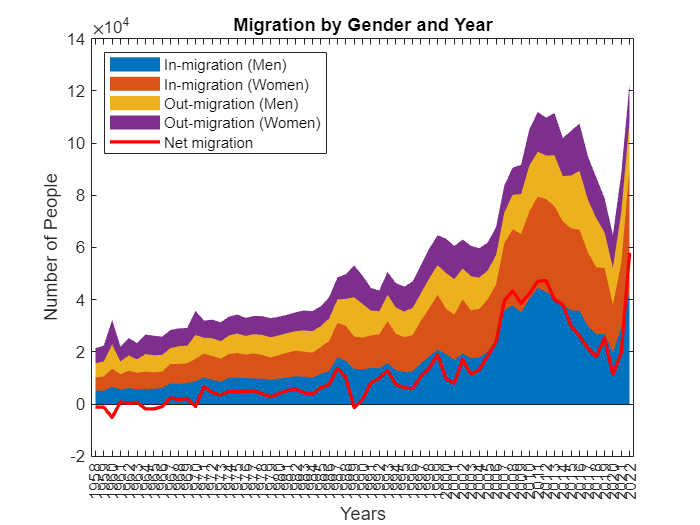

% Extract years, in-migration, out-migration, and net migration data
years = flyttingetetterrogkjnn_V1.VarName1;
in_migration_men = flyttingetetterrogkjnn_V1.InnflyttingerMenn;
in_migration_women = flyttingetetterrogkjnn_V1.InnflyttingerKvinner;
out_migration_men = flyttingetetterrogkjnn_V1.UtflyttingerMenn;
out_migration_women = flyttingetetterrogkjnn_V1.UtflyttingerKvinner;
net_migration = (in_migration_men + in_migration_women) - (out_migration_men + out_migration_women);

% Create stacked area chart
figure;
area(years, [in_migration_men in_migration_women out_migration_men out_migration_women], 'LineStyle', 'none');
hold on;

% Set colors for the stacked area chart
cmap = [0.6 0.8 1; 1 0.6 0.6; 0.2 0.4 0.8; 0.8 0.2 0.2];
colormap(cmap);

% Create difference plot with a single color (purple)
plot(years, net_migration, 'LineWidth', 2, 'Color', [1 0.0 0.0]);

% Add labels, legend, and adjust axes
xlabel('Years');
ylabel('Number of People');
title('Migration by Gender and Year');
legend('In-migration (Men)', 'In-migration (Women)', 'Out-migration (Men)', 'Out-migration (Women)', 'Net migration', 'Location', 'northwest');
xlim([years(1) years(end)]);
hold off;